# Spin echo

## Load data

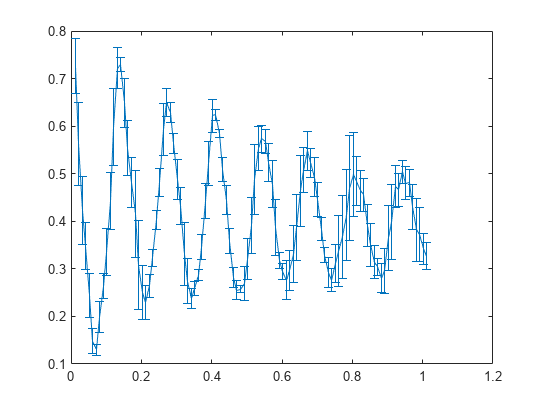

clear all
% Yb-173 Ramsey 180:20:0s 6 ms + 0:7:210 ms
main_dir='\\Artemis-pc\e\Data\2022-10-13\Abs-1891';
load([main_dir,'\average.mat'],'precess_1_list','precess_2_list','mean_1','std_1','weight_1','amp_list','amp_error','amp_weight','matrix_1','fi_result','precess_1_list','precess_1_list_plot');

% Yb-173 Spin echo
main_dir='\\Artemis-pc\e\Data\2022-10-11\Abs-745';
load([main_dir,'\result.mat'],'relativeOD');

% Yb-173 Spin echo -tensor

load(['\\Artemis-pc\e\Data\2022-10-19\Abs-1284','\average.mat'],'xlist','phase_mean','phase_std');

errorbar(xlist,phase_mean,phase_std)

xlist_T=xlist;
phase_mean_T=phase_mean;
phase_std_T=phase_std;

## Ramsey decay

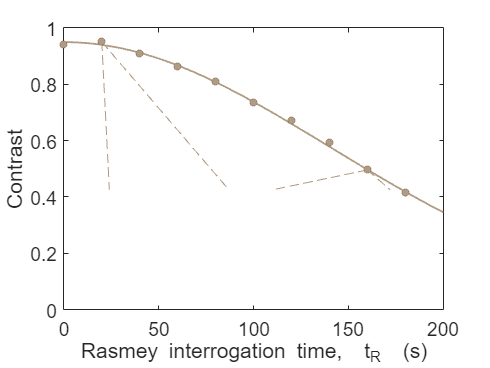

colors=npg(100); 

eqn='a*exp(-x^2/b^2)';
startpoints=[1 500];
lower=[0.8 100];
upper=[1 1000];

fi=fit(precess_2_list',amp_list,eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',amp_weight);
f1=figure;


% line indicator
line([precess_2_list(9) 24],[amp_list(9) 0.425],'LineStyle',"--",'Color',colors(100,:))
line([precess_2_list(9) 87],[amp_list(9) 0.425],'LineStyle',"--",'Color',colors(100,:))

line([precess_2_list(2) 110],[amp_list(2) 0.425],'LineStyle',"--",'Color',colors(100,:))
line([precess_2_list(2) 172],[amp_list(2) 0.425],'LineStyle',"--",'Color',colors(100,:))
hold on

h2=plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on
h3=errorbar(precess_2_list',amp_list,amp_error,'o');

box on
xlim([0 200])
ylim([0 1])
set(gca,'FontSize',16)
xlabel('Rasmey interrogation time, \it t_{R} \rm (s)')
ylabel('Contrast')
%ylabel('$\mathrm{Contrast}$','Interpreter','latex')

h2.Color=colors(100,:);

h3.MarkerSize=6;
h3.Color=colors(91,:);
h3.MarkerEdgeColor=colors(91,:);
h3.MarkerFaceColor=colors(100,:);
h3.CapSize=0;


ax1=gca;

fi.b

ans = 198.8221

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     0.0044    2.0122


## Spin echo

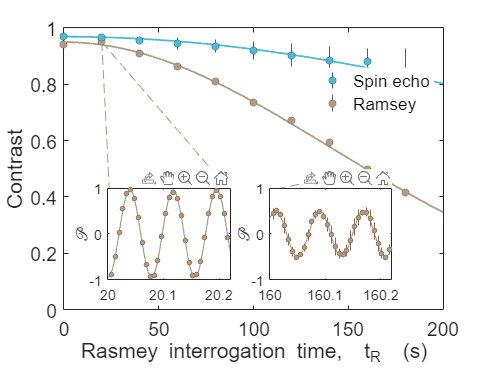



xlist=fliplr(0:20:180);
repeat_se = length(relativeOD)/length(xlist);
reshape_phase=reshape(relativeOD,repeat_se,length(xlist));
%reshape_phase=reshape(relativeOD,length(xlist),repeat_se)/2+1/2;

%reshape_phase(1:10,:)=[];

phase_mean=mean(reshape_phase);
phase_std=std(reshape_phase);
phase_weight=1./phase_std.^2;

hold on

eqn='a*exp(-x^2/b^2)';
startpoints=[1 500];
lower=[0.8 100];
upper=[1 1000];

fi=fit(xlist',phase_mean',eqn,'Start',startpoints,'Lower',lower,'Upper',upper,'Weight',phase_weight);
h4=plot((1:1:200),fi(1:1:200),'LineWidth',1.5,'Color',colors(5,:));
hold on

h5=errorbar(xlist',phase_mean,phase_std,'o');

h4.Color=colors(12,:);
h5.MarkerSize=6;
h5.Color=colors(31,:);
h5.MarkerEdgeColor=colors(31,:);
h5.MarkerFaceColor=colors(12,:);
h5.CapSize=0;


legend([h5 h3],{'Spin echo','Ramsey'},'Position',[0.66 0.7 0.2 0.1])

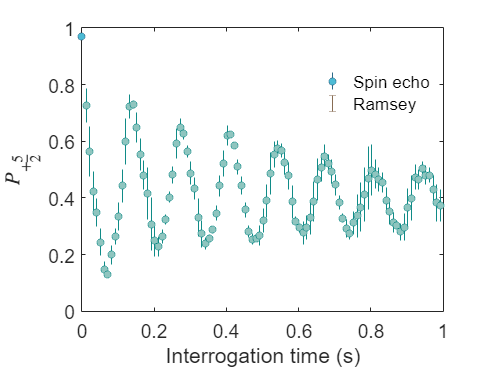

legend('boxoff')


fi.b

ans = 460.3852

temp = confint(fi);
(temp(2,:)-temp(1,:))/4

ans =     0.0017   23.2353


## Sub sub figure

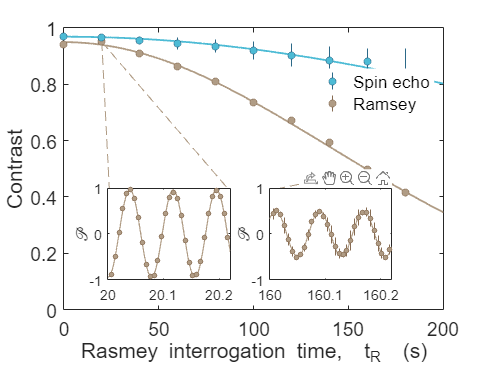

% Sub sub figure 1
h_2=axes('Position',[0.22 0.24 0.25 0.25]);
fit_2=fi_result{9};
h2=plot(precess_1_list_plot,fit_2(precess_1_list_plot),'LineWidth',1);
hold on
h3=errorbar(precess_1_list,mean_1(:,:,9),std_1(:,:,9),'o');
xlim([0 220])
ylim([-1 1])
set(gca,'FontSize',12)
%xlabel('t (ms)')
ylabel('$\mathcal{P}$','Interpreter','latex','Position',[-30 0])

xticks([0 100 200])
xticklabels({'20','20.1','20.2'})
set(gca,'XTickLabelRotation',0)
h2.Color=colors(100,:);

h3.MarkerSize=4;
h3.Color=colors(91,:);
h3.MarkerEdgeColor=colors(91,:);
h3.MarkerFaceColor=colors(100,:);
h3.CapSize=0;

% Sub sub figure 2
h_2=axes('Position',[0.55 0.24 0.25 0.25]);
fit_2=fi_result{2};
h2=plot(precess_1_list_plot,fit_2(precess_1_list_plot),'LineWidth',1);
hold on
h3=errorbar(precess_1_list,mean_1(:,:,2),std_1(:,:,2),'o');
xlim([0 220])
ylim([-1 1])
set(gca,'FontSize',12)
%xlabel('t (ms)')
ylabel('$\mathcal{P}$','Interpreter','latex','Position',[-30 0])

xticks([0 100 200])
xticklabels({'160','160.1','160.2'})
set(gca,'XTickLabelRotation',0)

h2.Color=colors(100,:);

h3.MarkerSize=4;
h3.Color=colors(91,:);
h3.MarkerEdgeColor=colors(91,:);
h3.MarkerFaceColor=colors(100,:);
h3.CapSize=0;

## Save

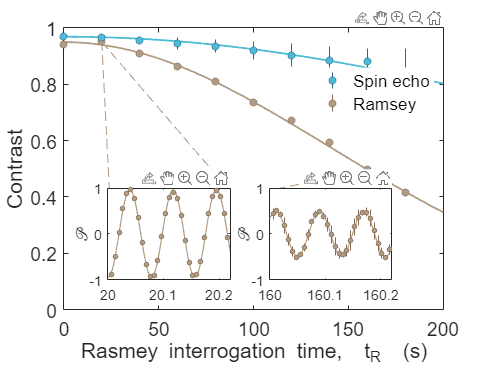


saveas(f1,['\\Artemis-pc\e\Data\DataForPub','\Figure3_0.png'])
print(gcf, ['\\Artemis-pc\e\Data\DataForPub','\Figure3_1.png'],'-r300','-dpng');

## tensor estimation

f2=figure

f2 =   Figure (21) - 属性:

      Number: 21
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  显示 所有属性


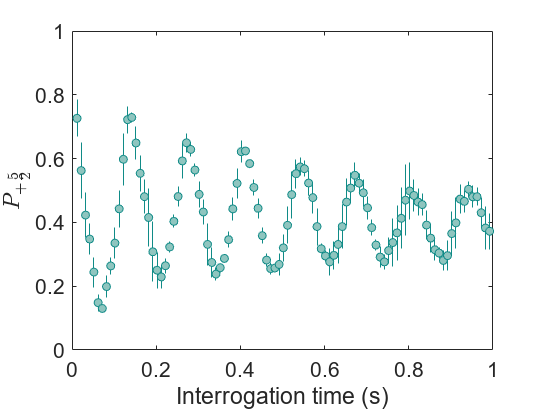

h6=errorbar(xlist_T,phase_mean_T,phase_std_T,'o');

%h4.Color=colors(12,:);
h6.MarkerSize=6;
h6.Color=colors(26,:);
h6.MarkerEdgeColor=colors(26,:);
h6.MarkerFaceColor=colors(65,:);
h6.CapSize=0;

xlim([0 1])
ylim([0 1])
set(gca,'FontSize',16)
xlabel('Interrogation time (s)')
ylabel('$P_{+\frac{5}{2}}$','Interpreter','latex')
saveas(f2,['\\Artemis-pc\e\Data\DataForPub','\Figure4_0.png'])
print(gcf, ['\\Artemis-pc\e\Data\DataForPub','\Figure4_1.png'],'-r300','-dpng');